# Séance 1

## 1. Calcul de l'expression récurrente d'un premier ordre par les 4 méthodes de discrétisation

Le système que nous allons analyser à la fonction de transfert suivante:


$$H(s) = \frac{1}{s+1}$$


**a) Euler à gauche (forward)**

Pour obtenir l'équation du système discrétisé à l'aide de la méthode d'Euler à gauche, on doit remplacer les *s* par 


$$s \to \frac{z-1}{h}$$


Si on fait ça, on obtient le système discrétisé suivant:


$$H_{d,Euler1}(z) = \frac{1}{\frac{z-1}{h} + 1} = \frac{h}{z-1+h}$$


**b) Euler à droite (backward)**

Pour obtenir l'équation du système discrétisé à l'aide de la méthode d'Euler à droite, on doit remplacer les *s* par 


$$s \to \frac{z-1}{hz}$$


Si on fait ça, on obtient le système discrétisé suivant:


$$H_{d,Euler2}(z) = \frac{1}{\frac{z-1}{hz} + 1} = \frac{hz}{z-1+hz} = \frac{hz}{z(h+1)-1}$$


**c) Bilinéaire**

Pour obtenir l'équation du système discrétisé à l'aide de la méthode bilinéaire (Tustin), on doit remplacer les *s* par 


$$s \to \frac{2(z-1)}{h(z+1)}$$


Si on fait ça, on obtient le système discrétisé suivant:


$$H_{d,Bilinéaire}(z) = \frac{1}{\frac{2(z-1)}{h(z+1)} + 1} = \frac{h(z+1)}{2(z-1) + h(z+1)}$$


**d) Equivalent échantilloné bloqué**

???

## 2. Créer un script Matlab qui montre:

**a) Les réponses temporelles des quatre expressions trouvées comparées avec la réponse exacte du système continu. ** 

h = 0.1;
s = tf('s');
z = tf('z', h);

Hc = 1 / (s + 1)


Hc =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.




% Euler à gauche
sg = (z - 1)/h;
Hg = 1 / (sg + 1)


Hg =
 
    0.1
  -------
  z - 0.9
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% Euler à droite
sd = (z-1)/(h*z);
Hd = 1 / (sd + 1)


Hd =
 
    0.1 z
  ---------
  1.1 z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% Bilinéaire
Hb = c2d(Hc, h, 'tustin')


Hb =
 
  0.04762 z + 0.04762
  -------------------
      z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% ZOH
Hzoh = c2d(Hc, h)


Hzoh =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Maintenant que nous avons nos fonctions de transferts discrétisés par les 4 méthodes dans Matlab, nous pouvons les analyser. Nous allons commencer par faire un plot de leurs réponse indicielle par rapport a celle du système continu.

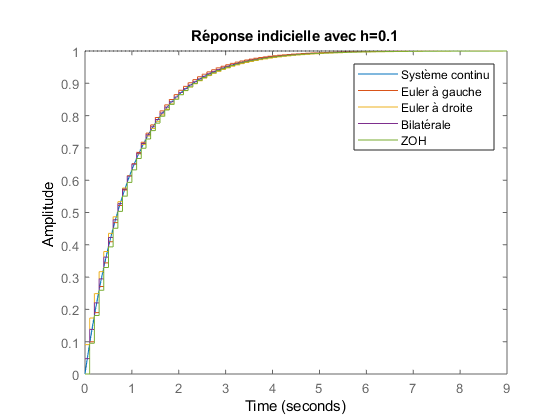

hold on;
step(Hc);
step(Hg);
step(Hd);
step(Hb);
step(Hzoh);
legend('Système continu', 'Euler à gauche', 'Euler à droite', 'Bilatérale', 'ZOH');
title("Réponse indicielle avec h=0.1");
hold off;

**b) L'influence de la période d'échantillonage h** 

On peut répéter les étapes ci-dessus pour des valeurs de *h* différentes. Prenons par exemple *h = 0.01*, *h = 0.5* et *h = 1.0*.

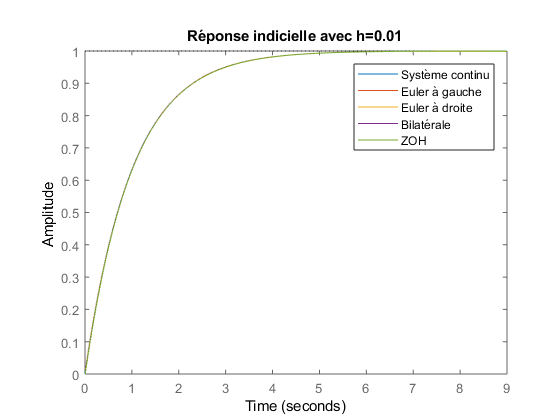

openfig('comp_h_0_01.fig');

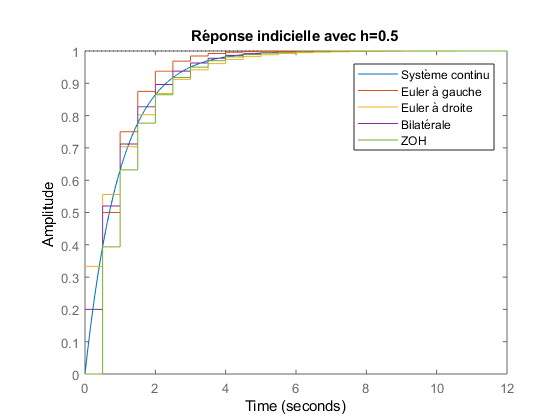

openfig('comp_h_0_5.fig');

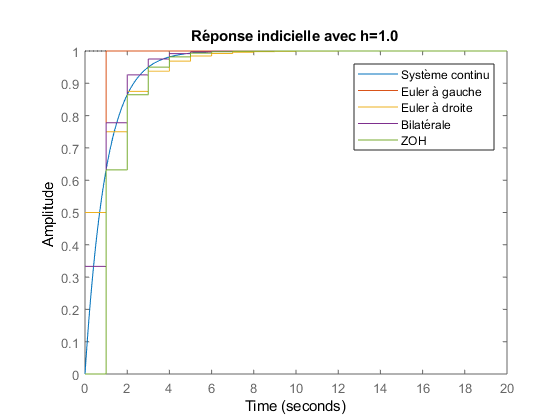

openfig('comp_h_1_0.fig');

On peut voir que pour une petite période d'échantillonage, la discrétisation colle très bien au système réel. Mais quand la période d'échantillonage augmente, les sytèmes discrétisés sont de plus en plus grossiers. 

La période d'échantillonage a également un effet sur les pôles.

h1 = 0.1;
h2 = 0.5;
h3 = 1.0;
h4 = 2.0;
h5 = 4.0;
z1 = tf('z', h1);
z2 = tf('z', h2);
z3 = tf('z', h3);
z4 = tf('z', h4);
z5 = tf('z', h5);

Pour la discrétisation avec Euler à gauche, nous pouvons voir sur la figure ci-dessous que les pôles se déplacent vers la gauche quand la période d'échantillonage augmente. Nous pouvons également tirer cette conclusion par l'équation trouvée plus haut. Le pôle est donné par:


$$p = 1-h$$


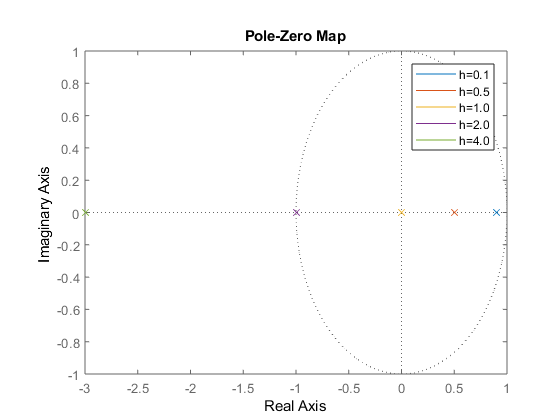

% Euler à gauche
sg1 = (z1 - 1)/h1;
sg2 = (z2 - 1)/h2;
sg3 = (z3 - 1)/h3;
sg4 = (z4 - 1)/h4;
sg5 = (z5 - 1)/h5;
Hg1 = 1 / (sg1 + 1);
Hg2 = 1 / (sg2 + 1);
Hg3 = 1 / (sg3 + 1);
Hg4 = 1 / (sg4 + 1);
Hg5 = 1 / (sg5 + 1);

figure;
pzmap(Hg1, Hg2, Hg3, Hg4, Hg5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

Pour la discrétisation avec Euler à droite, nous pouvons voir que les pôles se déplacent également vers la gauche, mais pas de façon linéaire. Par l'équation, on obtient que le pôle est donné par:


$$p = \frac{1}{h+1}$$


Le pôle va donc tendre vers zéro et non plus vers l'infini négatif.

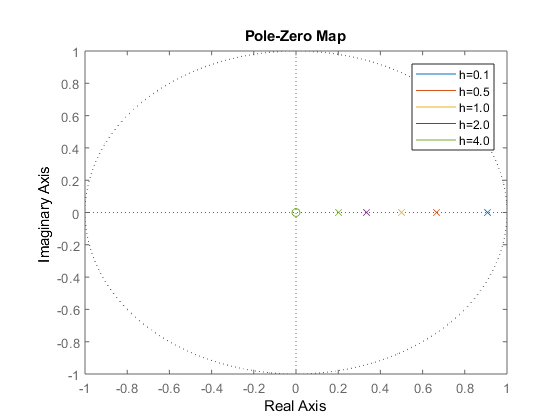

% Euler à droite
sd1 = (z1 - 1)/(h1*z1);
sd2 = (z2 - 1)/(h2*z2);
sd3 = (z3 - 1)/(h3*z3);
sd4 = (z4 - 1)/(h4*z4);
sd5 = (z5 - 1)/(h5*z5);
Hd1 = 1 / (sd1 + 1);
Hd2 = 1 / (sd2 + 1);
Hd3 = 1 / (sd3 + 1);
Hd4 = 1 / (sd4 + 1);
Hd5 = 1 / (sd5 + 1);

figure;
pzmap(Hd1, Hd2, Hd3, Hd4, Hd5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

Pour la méthode bilinéaire, le pôle est donné par l'équation:


$$p = \frac{2-h}{2+h}$$


On peut donc voir que pour la valeur de *h = 2*, le pôle se retrouve à 0 et si h augmente encore le pôle va tendre vers -1.

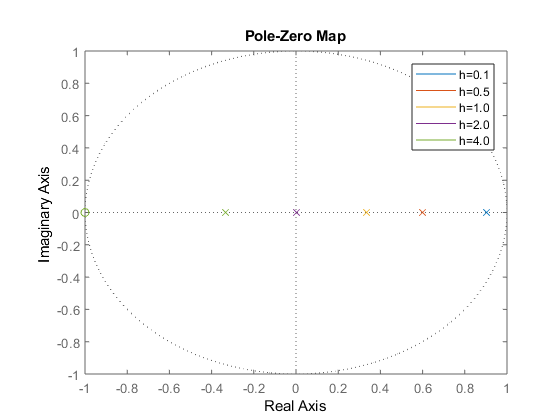

% Bilinéaire
Hb1 = c2d(Hc, h1, 'tustin');
Hb2 = c2d(Hc, h2, 'tustin');
Hb3 = c2d(Hc, h3, 'tustin');
Hb4 = c2d(Hc, h4, 'tustin');
Hb5 = c2d(Hc, h5, 'tustin');

figure;
pzmap(Hb1, Hb2, Hb3, Hb4, Hb5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

Pour la méthode de discrétisation 'Sample and Hold', les pôles ***???***

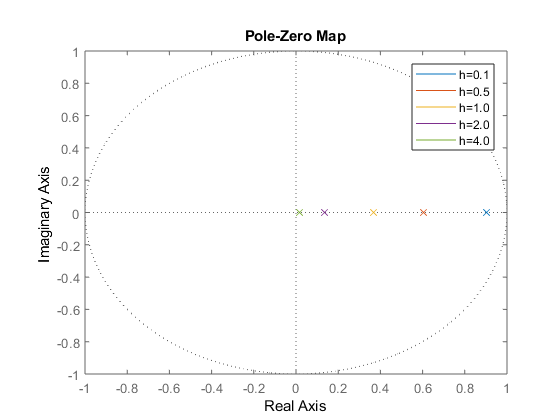


% ZOH
Hzoh1 = c2d(Hc, h1);
Hzoh2 = c2d(Hc, h2);
Hzoh3 = c2d(Hc, h3);
Hzoh4 = c2d(Hc, h4);
Hzoh5 = c2d(Hc, h5);

figure;
pzmap(Hzoh1, Hzoh2, Hzoh3, Hzoh4, Hzoh5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

**c) Quelle(s) méthode(s) de discrétisation rend(ent) le système discrétisé instable **

Par les résultats obtenus précédamment, nous pouvons tirer les conclusions suivants:

La méthode de Euler par la gauche peut rendre le système instable en le discrétisant pour des valeurs de *h* qui sont grandes. Mais nous pouvons dire que si le système discret est stable, alors le système continu l'est obligatoirement aussi.

La méthode de Euler par la droite ne rendra jamais un système instable en le discrétisant. Donc si le système continu est stable, le système discrétisé le sera également, indépendamment de la période d'échantillonage choisit.

La méthode bilinéaire ne rendra également jamais un système instable en le discrétisant. Si le système continu est stable, le système discrétisé le sera aussi, indépendamment de la période d'échantillonage choisit. De plus, si le système discrétisé est stable nous pouvons également dire que le système continu l'est nécessairement aussi.

**d)** **Une comparaison des réponses fréquentielles**

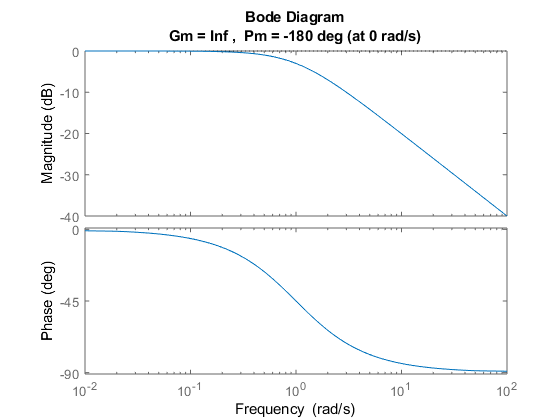

margin(Hc);

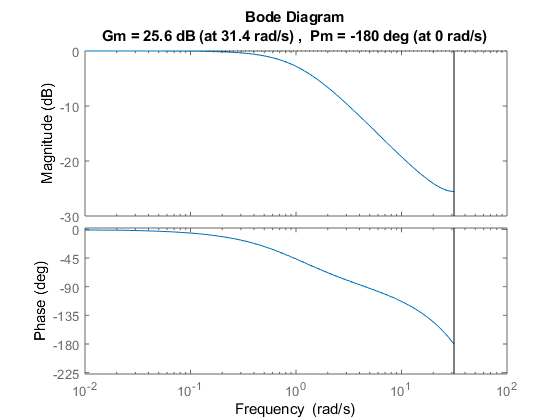

margin(Hg);

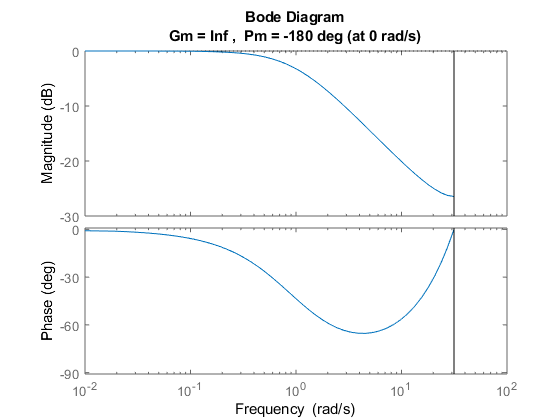

margin(Hd);

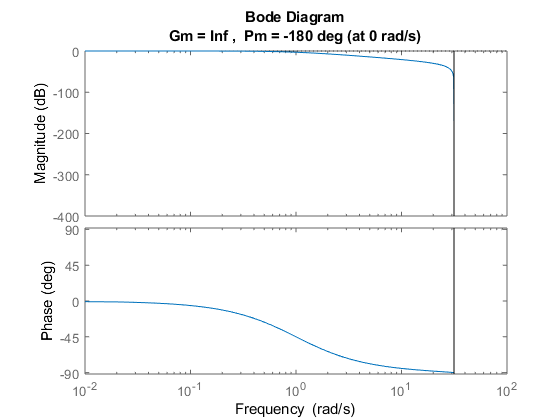

margin(Hb);

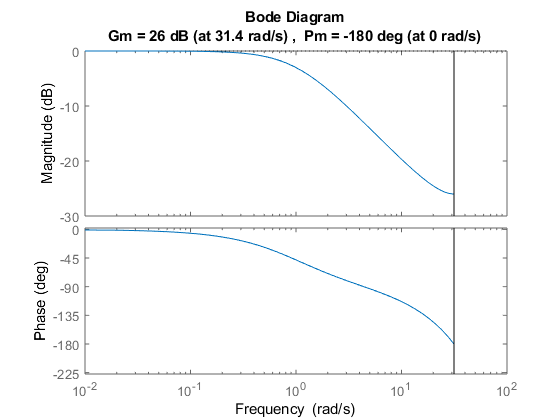

margin(Hzoh);

## 3. Calcul du gain critique d'un système du premier ordre bouclé avec un régulateur P

Un système de premier ordre à une fonction de transfert de la forme:


$$G_o(s) = \frac{K_o}{1+sT}$$


Si on veut implémenter un système de premier ordre bouclé avec un régulateur P, on obtient quelque chose comme dans le diagramme suivant.

La transmittance en boulce ouverte vaut alors:


$$G_{oc} = G_c \cdot G_o = K_p \cdot \frac{K}{1+sT}$$


Et on sait alors que la transmittance en boucle fermée vaut:


$$G_f = \frac{G_{oc}}{1 + G_{oc}} = \frac{\frac{K_p K_o}{1 + sT}}{1 + \frac{K_pK_o}{1 + sT}} = \frac{K_p K_o}{sT + 1 + K_pK_o} $$


Pour un système de premier ordre, la phase ne coupera jamais -180° et le système n'est donc jamais instable. On peut vérifier ça à l'aide de Matlab

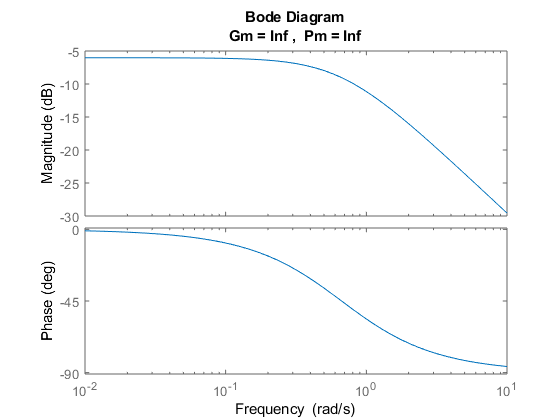

Ko = 1;
Kp = 1;
T = 3;
Go = Ko / (1+s*T);
R = Kp;
Goc = R * Go;
Gf = Goc / (1 + Goc);
margin(Gf);

Par contre, en discret, la fréquence d'échantillonage à un effet sur la stabilité du système.


$$G_o(z) = \frac{K_pK_o \left( 1 - e^{ \frac{ -T_s}{T}} \right) }{z - e^{ \frac{ -T_s}{T}}}$$



$$G_f(z) = \frac{K_pK_o \left( 1 - e^{ \frac{ -T_s}{T}} \right) }{z - e^{ \frac{ -T_s}{T}} + K_pK_o \left( 1 - e^{ \frac{ -T_s}{T}} \right)}$$


On peut voir que le pôle est donné par l'équation


$$z = K_pK_o \left( e^{ \frac{ -T_s}{T}} - 1 \right) + e^{ \frac{ -T_s}{T}} $$


Le système est stable si le module du pôle est < 1.

$|z| = 1 \Rightarrow K_pK_o < \frac{1 + e^{\frac{-T_s}{T}}}{1 - e^{\frac{-T_s}{T}}}$           ou           $T_s < T \ln \frac{1 - K_pK_o}{1 + K_pK_o}$

On peut voir que le temps d'échantillonage à une influence sur la stabilité du système. Et on peut vérifier ça à l'aide de Matlab

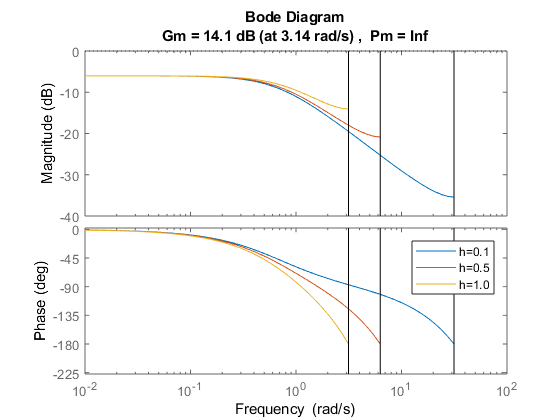

K = Kp * Ko;
T = 3;
Goz1 = (K * (1 - exp(-h1/T)))/(z1-exp(-h1/T) + K * (1 - exp(-h1/T)));
Goz2 = (K * (1 - exp(-h2/T)))/(z2-exp(-h2/T) + K * (1 - exp(-h2/T)));
Goz3 = (K * (1 - exp(-h3/T)))/(z3-exp(-h3/T) + K * (1 - exp(-h3/T)));
figure;
hold on;
margin(Goz1);
margin(Goz2);
margin(Goz3);
legend("h=0.1", "h=0.5", "h=1.0");
hold off;

On peut voir que le système devient de plus en plus instable, les marges de stabilités diminuent, quand la période d'échantilonnage augmente.

## 4. Déplacement des zéros du système échantillonné avec la période d'échantillonnage  

On utilise le système suivant pour analyser le déplacement des zéros en fonction de la période d'échantillonage:


$$H(s) = \frac{1}{(s+1)^3}$$


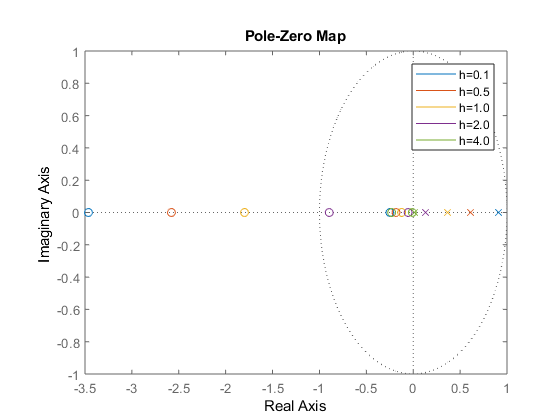

Hq4 = 1 / (s + 1)^3;
Hq4d1 = c2d(Hq4, h1);
Hq4d2 = c2d(Hq4, h2);
Hq4d3 = c2d(Hq4, h3);
Hq4d4 = c2d(Hq4, h4);
Hq4d5 = c2d(Hq4, h5);
figure;
hold on;
pzmap(Hq4d1);
pzmap(Hq4d2);
pzmap(Hq4d3);
pzmap(Hq4d4);
pzmap(Hq4d5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

On peut voir que les zéros se déplacent vers le centre quand on augmente la période d'échantillonage.